clc; clear; close all;

syms t
% Fixed parameters
zw = 1.5; % m
Tw = 10; % s
fw = 1/Tw; % Hz
nsh = 2; % Number of sheaves
ig = 11; % [-]
mpl = 18000; % kg
dD = 0.45; % m
dR = 0.5; % m
dp = 0.15; % m
mu_eq = 0.15; %
w0 = 5;
g = 9.81;

% Graphing the waves
zp = zw*sin((2*pi/Tw)*t)

$$zp = \frac{3\,\sin\left(\frac{\pi \,t}{5}\right)}{2}$$

zpDot = diff(zp, t)

$$zpDot = \frac{3\,\pi \,\cos\left(\frac{\pi \,t}{5}\right)}{10}$$

zpDotDot = diff(zpDot, t)

$$zpDotDot = -\frac{3\,\pi^{2}\,\sin\left(\frac{\pi \,t}{5}\right)}{50}$$

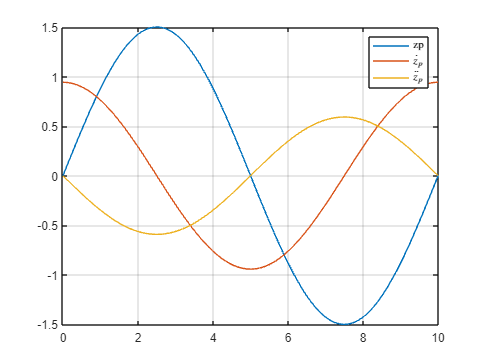


fplot(zp, [0 10])
hold on;
grid on;
fplot(zpDot, [0 10])
fplot(zpDotDot, [0 10])
legend('zp', '$\dot{z}_p$', '$\ddot{z}_p$','interpreter','latex')



% Calculating vertical speed and acceleration
vmax = vpa(subs(zpDot, t, solve(zpDotDot==0)))

$$vmax = 0.94247779607693797153879301498385$$

amax = abs(vpa(subs(zpDotDot, t, solve(diff(zpDotDot==0, t)))))

$$amax = 0.59217626406536151713006945999257$$


% Calculating gear ratio between wire and motor
n = 1/((dD*dp)/(2*nsh*dR*2*ig))%ig*(dR/dp)/(dD/2)*(nsh)

n = 651.8519


% Calculating load inertia expeienced by the motor(s)
J = mpl*(dD/2)^2*(1/n)^2

J = 0.0021


% Calculating max angular velocity and accelaration of the motors
thetaDotMax = n*vmax

$$thetaDotMax = 614.35589670200401107713915050799$$

thetaDotMax_RPM = thetaDotMax*(60/(2*pi))

$$thetaDotMax\_RPM = 5866.6666666666672339796168572228$$

thetaDotDotMax = n*amax

$$thetaDotDotMax = 386.01119435371713709219342577293$$


% Calculationg tourqe neede by one to accelerate the load
nm = 1;
m = ((mpl*g*dD*dp)/(2*nsh*dR*2*ig*nm))*(1+mu_eq*tanh(thetaDotMax/w0))

$$m = 311.52323863636362091256160056219$$



% Calculationg flow requierd
dm = 16/1e6;
nm = 5;

Qmax = (nm*dm*thetaDotMax_RPM/60)*6e4/(0.92)

$$Qmax = 510.14492753623193338953190062807$$


theoreticalWork = mpl*g*3

theoreticalWork = 529740